## Image segmentation using region growing

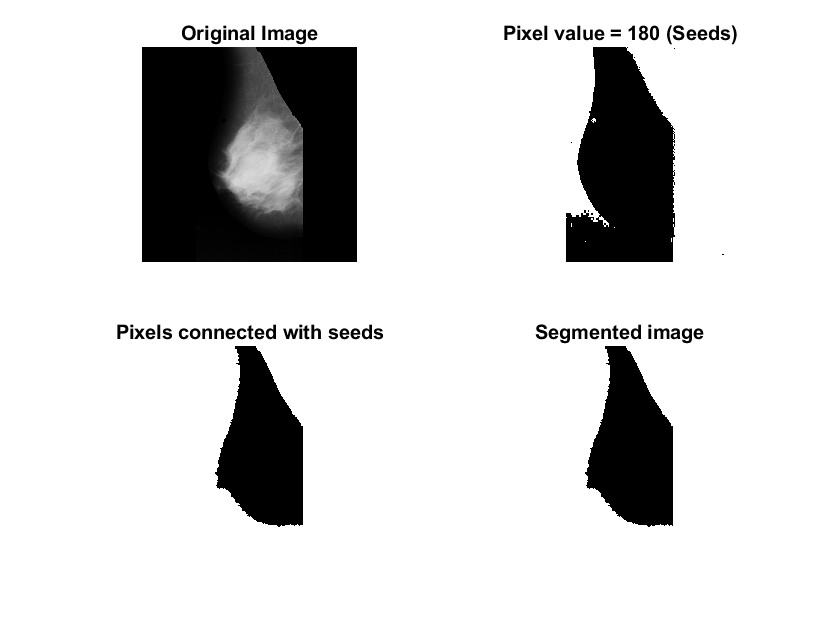

      483020        2338
        2338     1605362



       Contrast: 0.0022
    Correlation: 0.9937
         Energy: 0.6415
    Homogeneity: 0.9989



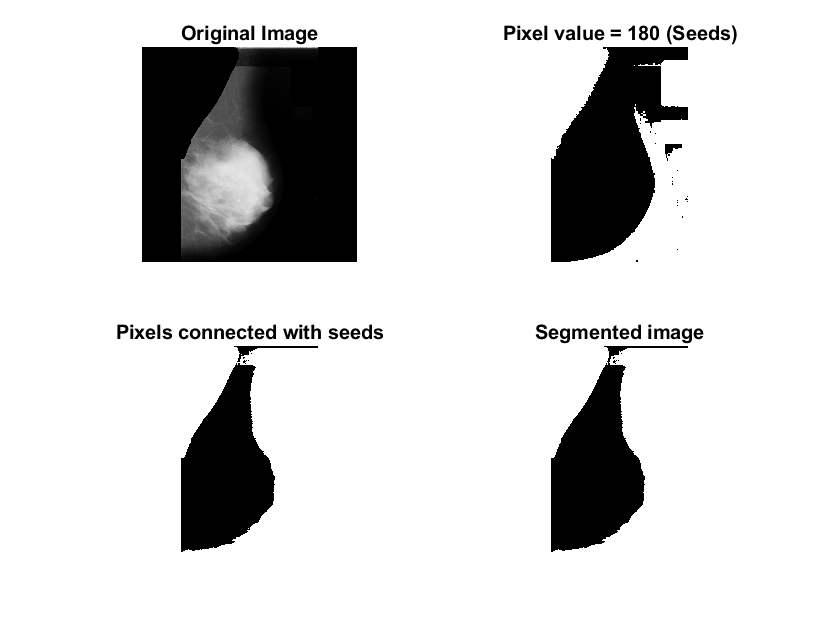

      528826        3886
        3886     1556460



       Contrast: 0.0037
    Correlation: 0.9902
         Energy: 0.6168
    Homogeneity: 0.9981



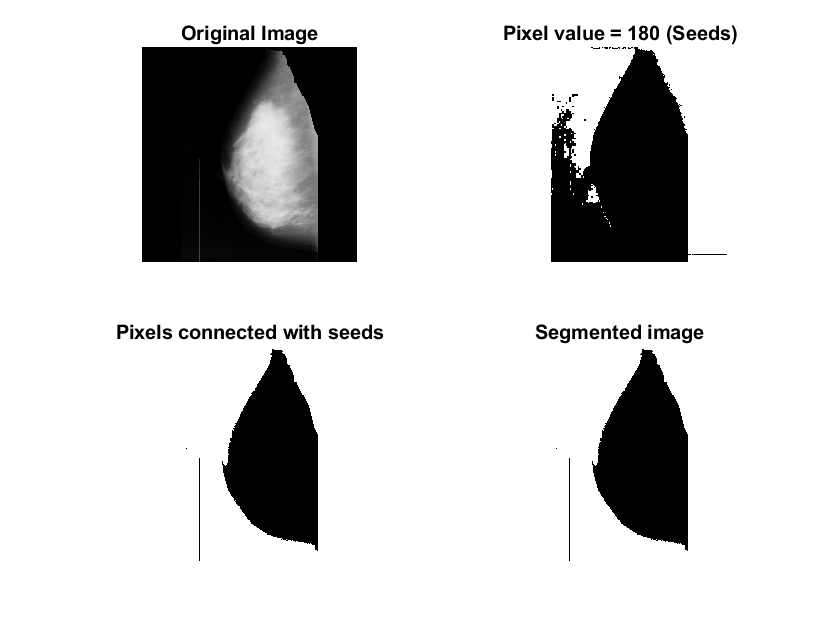

      574184        3538
        3538     1511798



       Contrast: 0.0034
    Correlation: 0.9915
         Energy: 0.5970
    Homogeneity: 0.9983



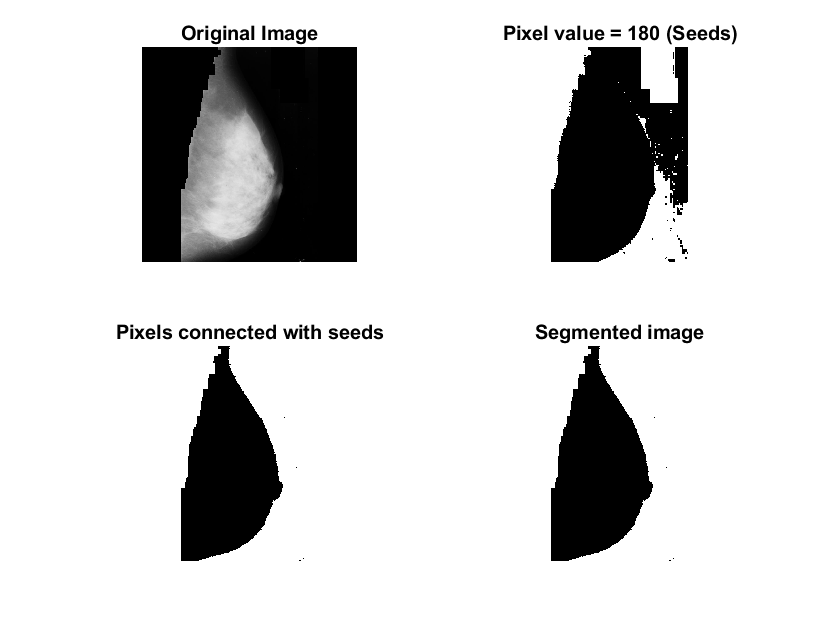

      616398        2811
        2811     1471038



       Contrast: 0.0027
    Correlation: 0.9936
         Energy: 0.5807
    Homogeneity: 0.9987



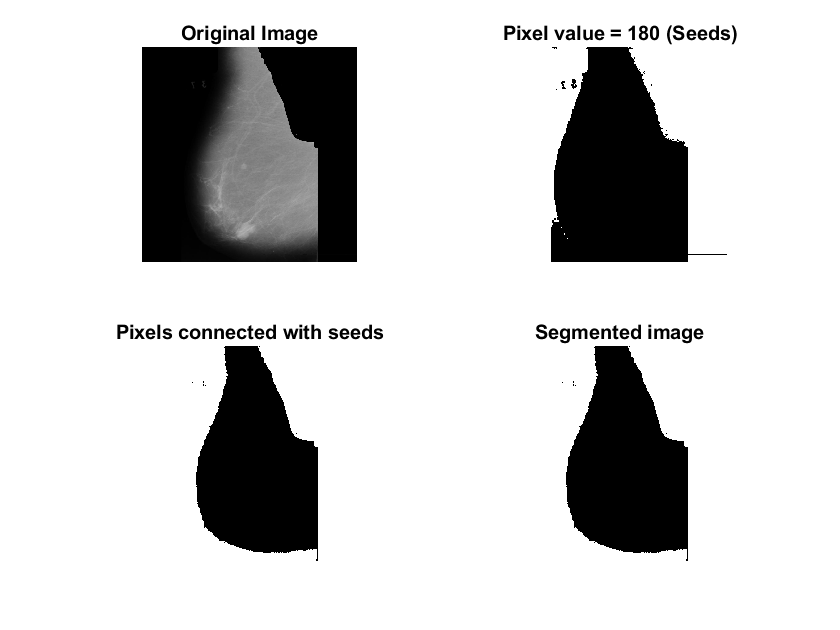

      817992        3133
        3133     1268800



       Contrast: 0.0030
    Correlation: 0.9937
         Energy: 0.5202
    Homogeneity: 0.9985



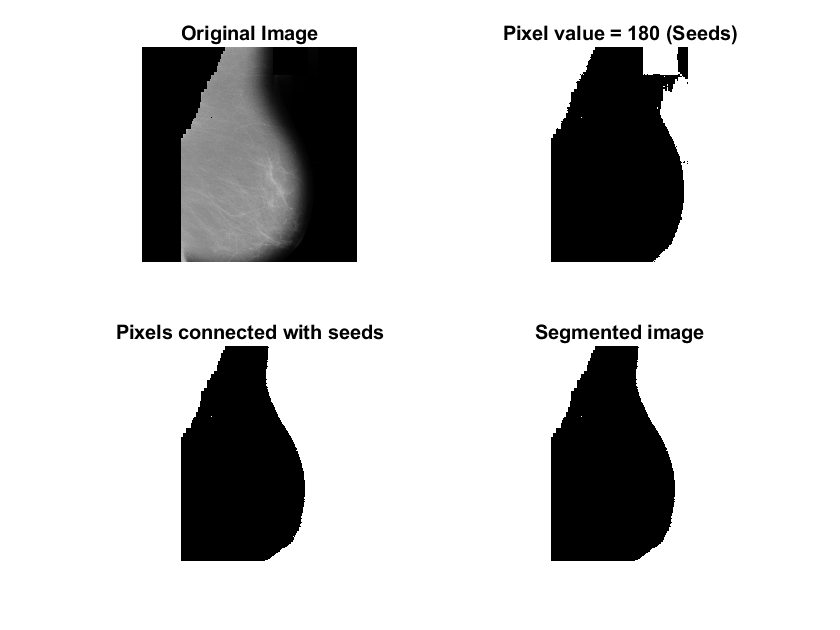

      930722        2574
        2574     1157188



       Contrast: 0.0025
    Correlation: 0.9950
         Energy: 0.5034
    Homogeneity: 0.9988



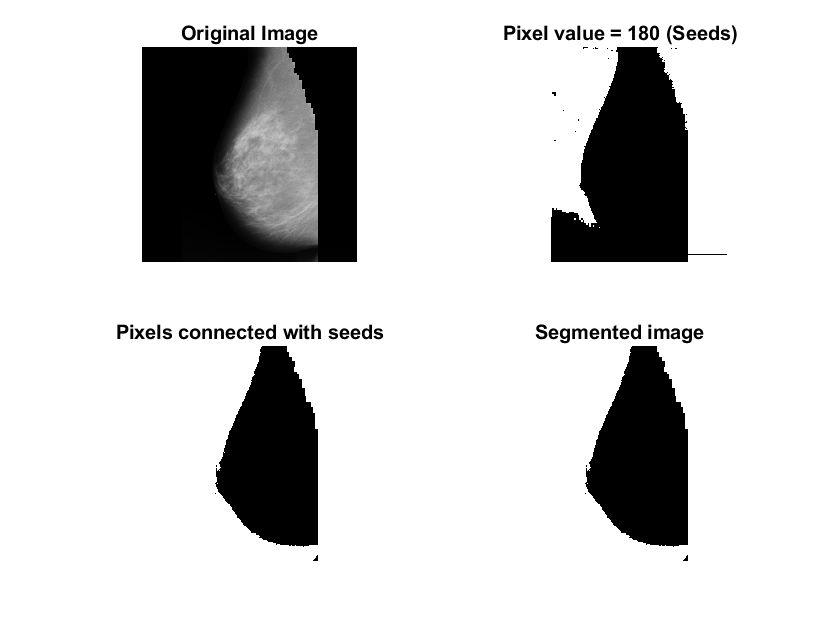

      663846        3064
        3064     1423084



       Contrast: 0.0029
    Correlation: 0.9933
         Energy: 0.5629
    Homogeneity: 0.9985



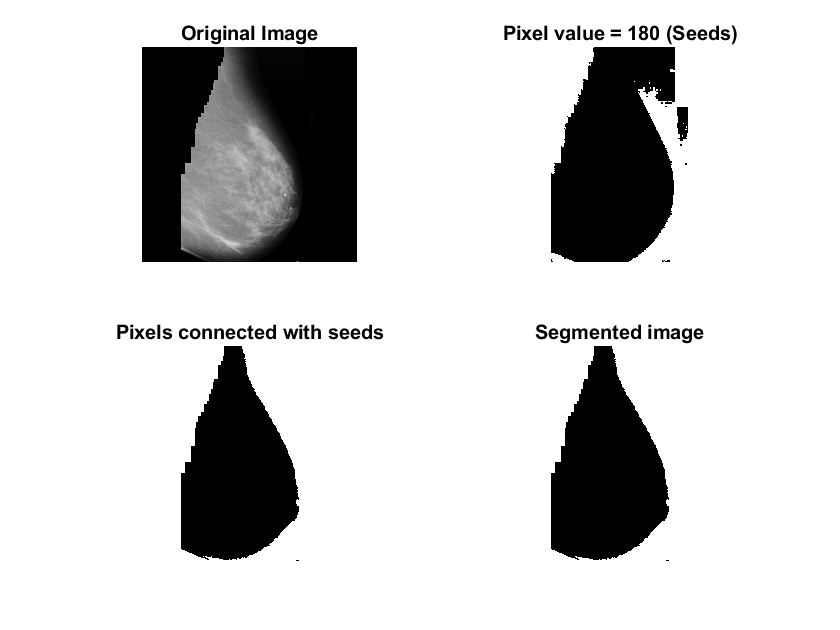

      759330        2877
        2877     1327974



       Contrast: 0.0027
    Correlation: 0.9941
         Energy: 0.5342
    Homogeneity: 0.9986



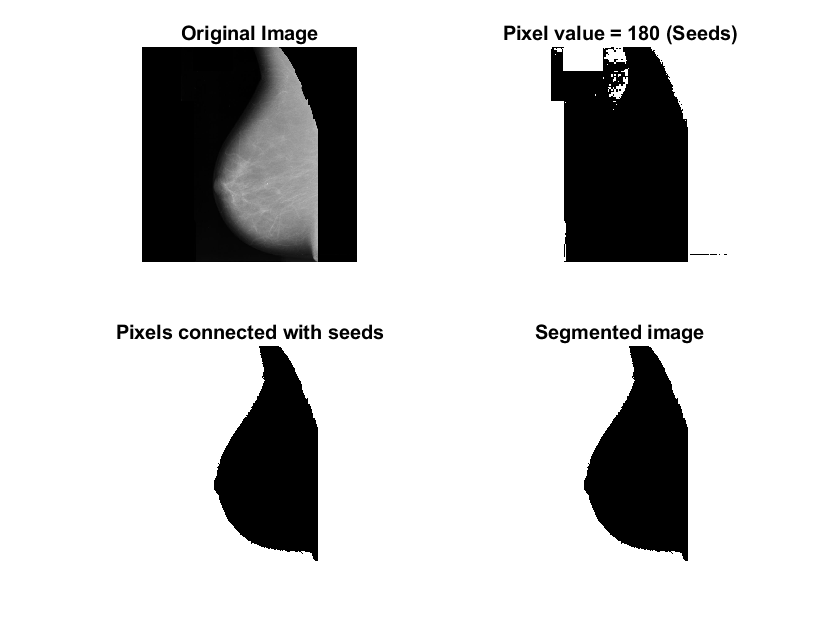

      668278        2878
        2878     1419024



       Contrast: 0.0028
    Correlation: 0.9937
         Energy: 0.5616
    Homogeneity: 0.9986



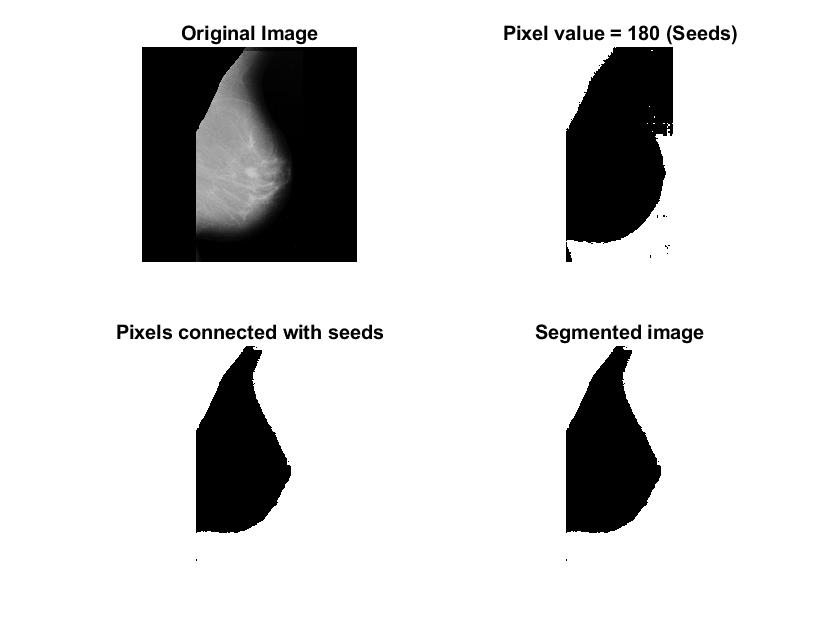

      528362        2786
        2786     1559124



       Contrast: 0.0027
    Correlation: 0.9930
         Energy: 0.6186
    Homogeneity: 0.9987



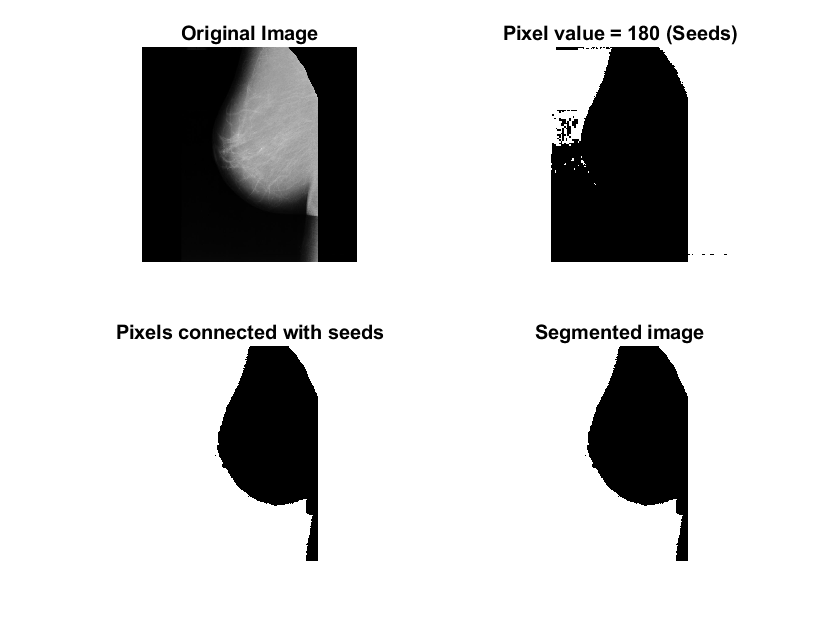

      601726        3176
        3176     1484980



       Contrast: 0.0030
    Correlation: 0.9926
         Energy: 0.5860
    Homogeneity: 0.9985



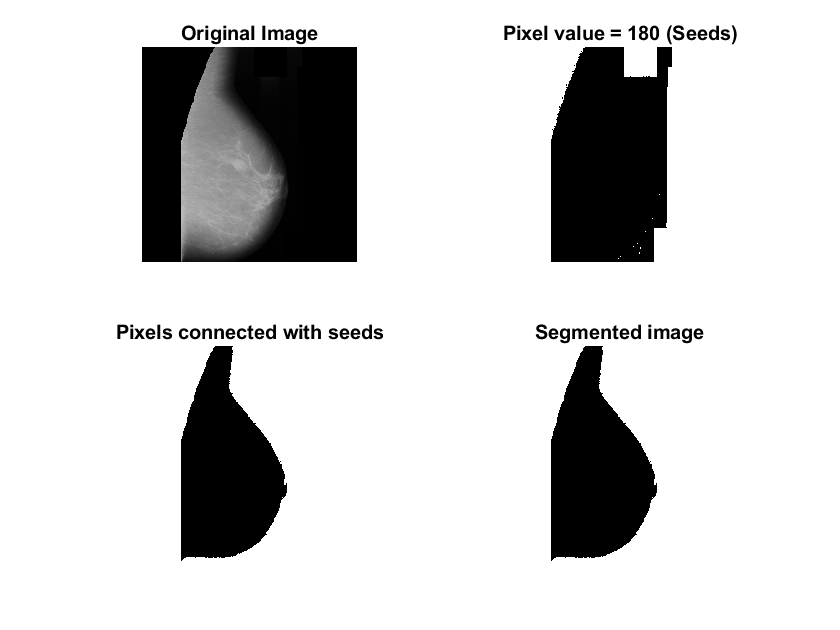

      674452        2923
        2923     1412760



       Contrast: 0.0028
    Correlation: 0.9936
         Energy: 0.5594
    Homogeneity: 0.9986



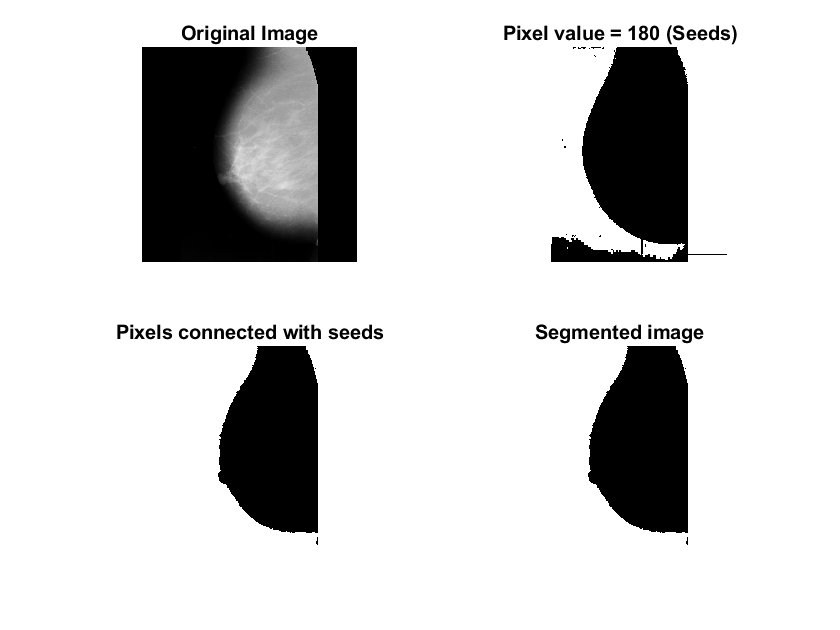

      683744        2931
        2931     1403452



       Contrast: 0.0028
    Correlation: 0.9936
         Energy: 0.5563
    Homogeneity: 0.9986



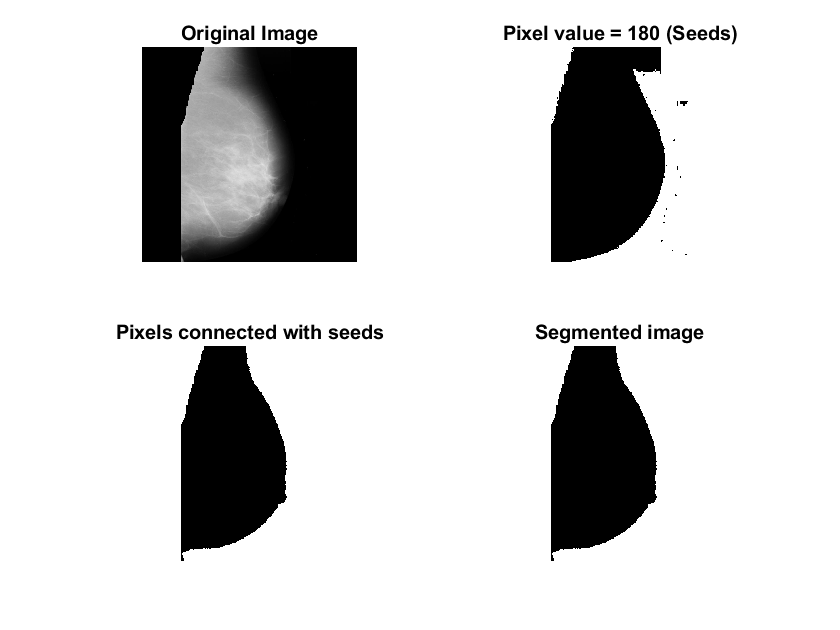

      758558        2694
        2694     1329112



       Contrast: 0.0026
    Correlation: 0.9944
         Energy: 0.5346
    Homogeneity: 0.9987



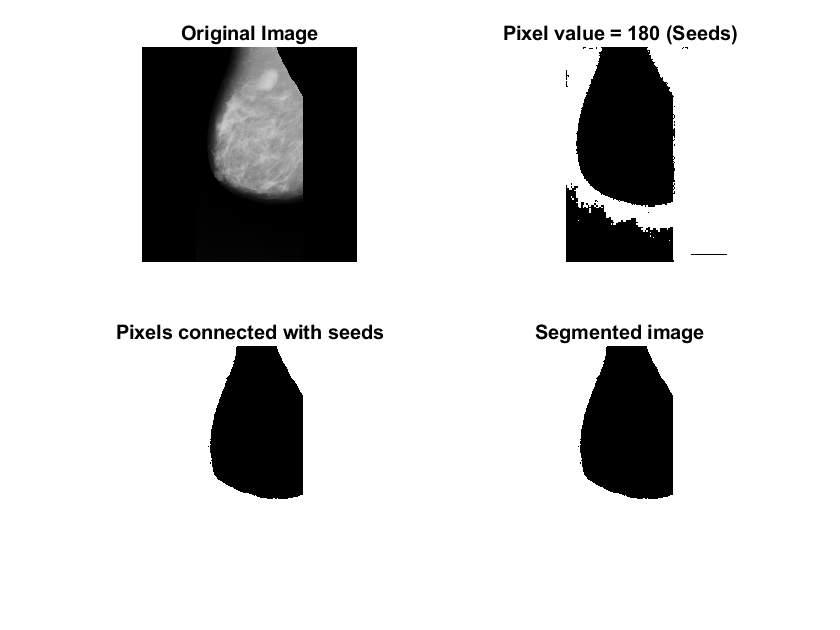

      528086        2152
        2152     1560668



       Contrast: 0.0021
    Correlation: 0.9946
         Energy: 0.6196
    Homogeneity: 0.9990



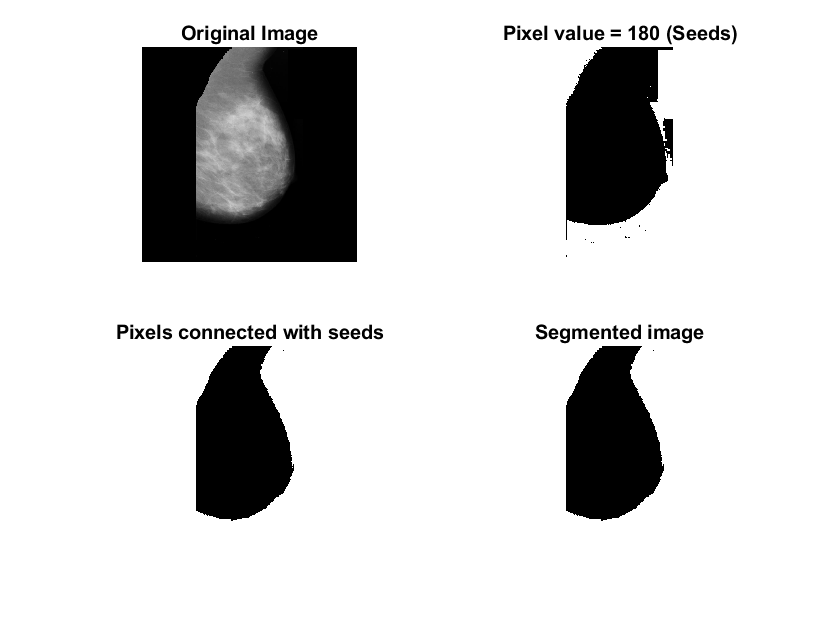

      587070        2924
        2924     1500140



       Contrast: 0.0028
    Correlation: 0.9931
         Energy: 0.5924
    Homogeneity: 0.9986



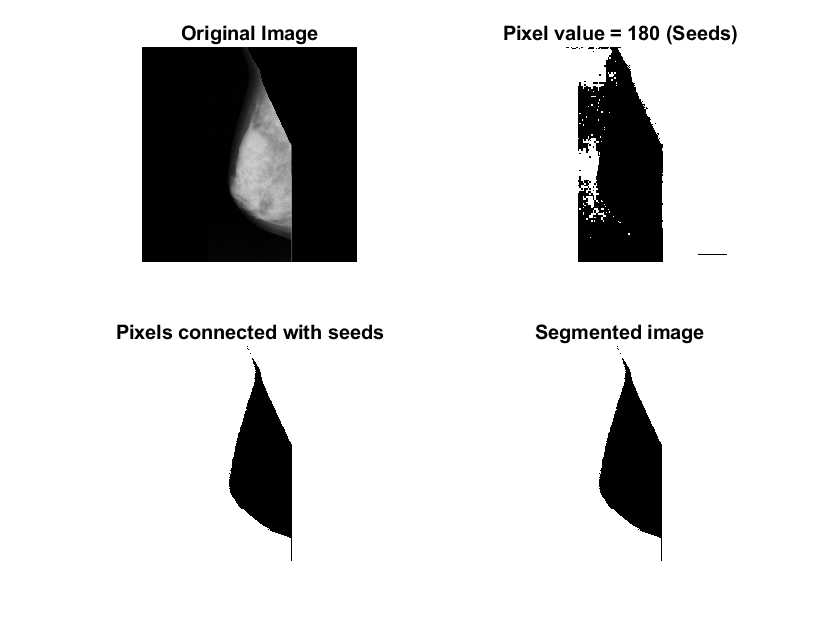

      305738        2345
        2345     1782630



       Contrast: 0.0022
    Correlation: 0.9911
         Energy: 0.7467
    Homogeneity: 0.9989



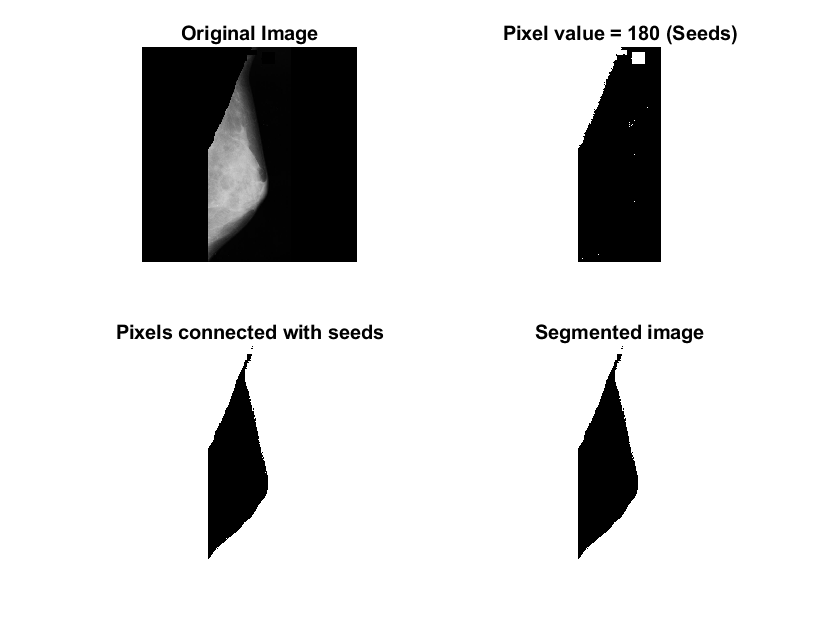

      310870        2797
        2797     1776594



       Contrast: 0.0027
    Correlation: 0.9895
         Energy: 0.7425
    Homogeneity: 0.9987



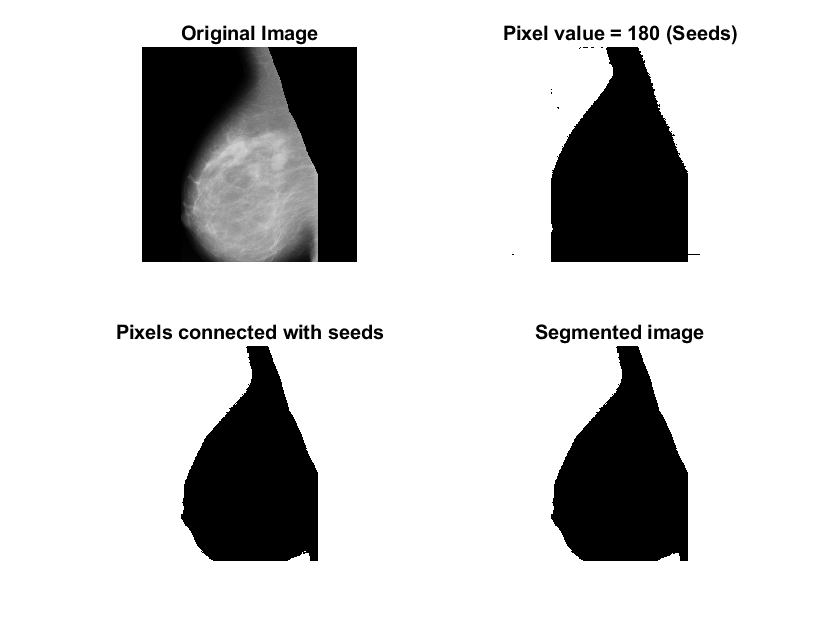

      880318        3237
        3237     1206266



       Contrast: 0.0031
    Correlation: 0.9937
         Energy: 0.5090
    Homogeneity: 0.9985



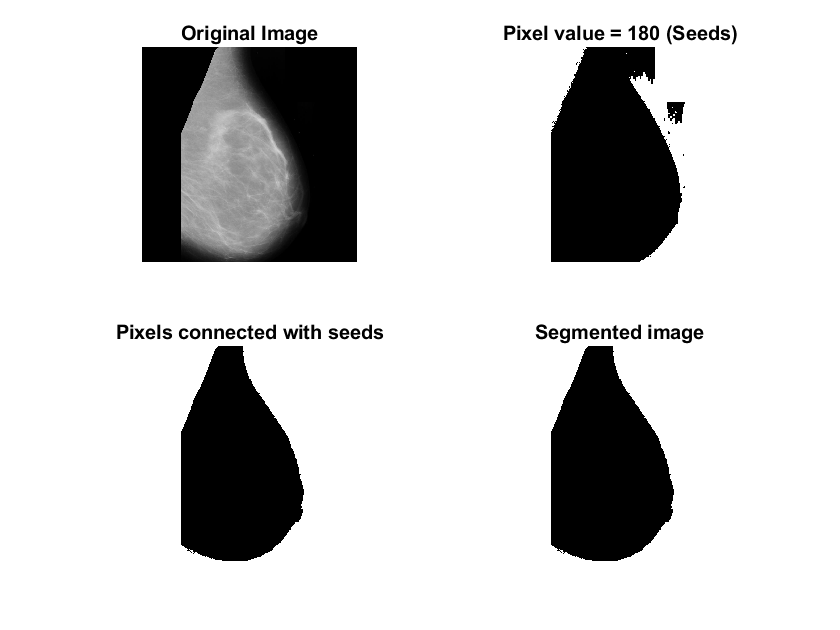

      865494        2637
        2637     1222290



       Contrast: 0.0025
    Correlation: 0.9948
         Energy: 0.5120
    Homogeneity: 0.9987



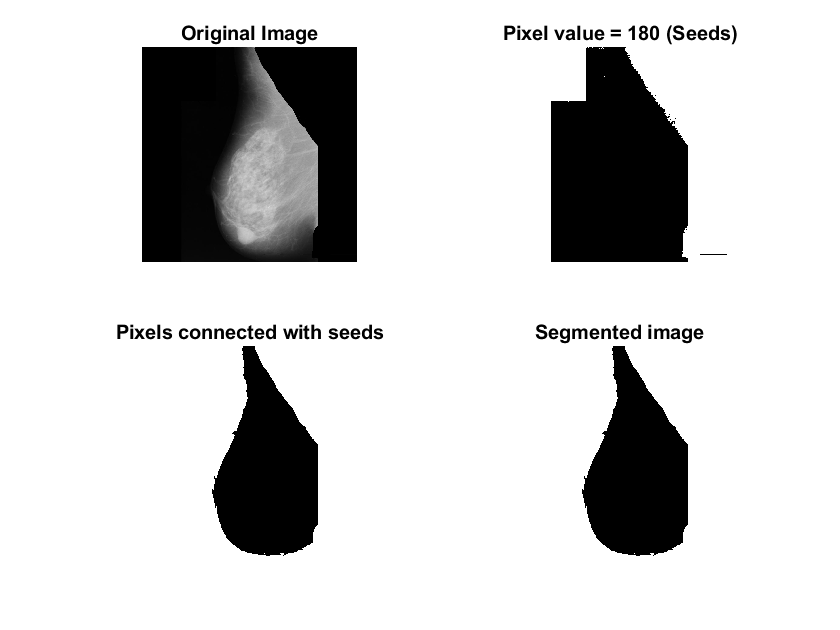

      647530        2917
        2917     1439694



       Contrast: 0.0028
    Correlation: 0.9935
         Energy: 0.5688
    Homogeneity: 0.9986



Index in position 1 exceeds array bounds (must not exceed 20).

%img="new/mdb001.tiff";

%put images file location here
%breastImds = imageDatastore(...
%    "C:\Users\Daniel Kee\Documents\Monash\FYP\FIT3162\fit3162\Code\MIAS(no muscle)");
%img="MIAS(no muscle)/mdb020.jpg";
breastImds=imageDatastore("MIAS(no muscle)");


condition = ['B';'B';'N';'N';'B';'N';'N';'N';'N';'B';'N';'B';'B';...
    'N';'B';'N';'B';'N';'B';'N';];
final = [];
j = 1;

%loop through the images
while(hasdata(breastImds))
    I = read(breastImds);
    I = rgb2gray(I);

    I = double(I);
    figure, subplot(2,2,1),imshow(uint8(I)),title('Original Image');
    Seeds = [180];
    SI = I == Seeds;
    subplot(2,2,2), imshow(SI, []),title('Pixel value = 180 (Seeds)');
    T = 30;
    TI = false(size(I));

    for i = 1:length(Seeds)
        seed_val = Seeds(i);
        S = abs(I-seed_val) <= T;
        TI = TI | S;
    end

    subplot(2,2,3), imshow(TI, []),title('Pixels connected with seeds');
    IM = imreconstruct(SI,TI);
    subplot(2,2,4), imshow(IM, []),title('Segmented image');
    
    
    [GLCM, SI] = graycomatrix(IM,'Offset',[1 1],'NumLevels',2,'GrayLimits',[],'Symmetric', true);
    stats = graycoprops(GLCM,'all');
    disp(GLCM);
    disp(stats);
    cell = struct2cell(stats);
    flipCell = transpose(cell);
    rowToAdd = [flipCell condition(j,1)];
    adding = [final;rowToAdd];
    final = adding;
    j = j+1;
end


Table = table(final);
filename = 'results.xlsx';
writetable(Table,filename,'Sheet',1,'Range','B3');
finalTable = readtable(filename);
finalTable.Properties.VariableNames{'final_1'} = 'Contrast';
finalTable.Properties.VariableNames{'final_2'} = 'Correlation';
finalTable.Properties.VariableNames{'final_3'} = 'Energy';
finalTable.Properties.VariableNames{'final_4'} = 'Homogeneity';
finalTable.Properties.VariableNames{'final_5'} = 'Actual Condition';
writetable(finalTable,filename,'Sheet',1,'Range','B3');